# The finite element method

***Note: ****For simplicity we only consider a 2D problem in divergence form and forgo the strict use of Sobolev space theory, needed for the rigerous treatment of the FEM. A comprehensive mathematical  formulation can instead found in the accompanying paper, for example.*

Let $\Omega \in \mathbf{R}^2$ be a domain with $\partial \Omega = \Gamma_1 \cup \Gamma_2, \ \Gamma_1^{\circ} \cap \Gamma_2^{\circ} = \emptyset$. Further let $f :\Omega \to \mathbf{R}$, $g:\Gamma_1 \to \mathbf{R}$, $h:\Gamma_2 \to \mathbf{R}$ be continous  and let $a:\Omega \to \mathbf{R}$ be continous, bounded and differentiable mappings. We seek to find a twice continously differentiable mapping $u: \bar{\Omega} \to \mathbf{R}$, which solves the strong form of the following partial differential equation (PDE).


$$
div \left ( a \, grad\, u \right ) = \nabla \cdot \left ( a \nabla u \right )  = -f, \text{in} \ \Omega, \\
u_{\vert \Gamma_1} = g, \text{ on } \Gamma_1, \\
\frac{\partial u}{\partial n}{\vert_{\Gamma_2} = h, \text{ on } \Gamma_2. 

$$


Here, Dirichlet bundary conditions (the first type) and Neumann boundary conditions (the second type) are considered.

Instead of solving the strong form of the PDE, we seek to solve the so called weak form of the PDE which is obtained by multiplying above equation with so called test functions $\varphi$ and integarting it over the whole domain.  In other words, find $u
$, such that for all test functions $\varphi$


$$\int \limits_{\Omega} \nabla \cdot \left ( a \nabla u \right ) \varphi \ \mathrm{dA} = - \int \limits_{\Omega} f \varphi \ \mathrm{dA}.$$


By exploting $\nabla \cdot \left ( u v\right) = \nabla u \cdot v + u \nabla \cdot v$ and Gauss' divergence theorem we have


$$\int \limits_{\Omega} a \nabla u \cdot \nabla \varphi \ \mathrm{dA} = \int\limits_{\partial \Omega} \varphi a \nabla u \cdot \vec{n} \ \mathrm{ds} + \int \limits_{\Omega} f \varphi \ \mathrm{dA}.$$


Where $\vec{n}$ denotes the puter normal to $\Omega$. Taking into accout only those testfunctions $\varphi$ that are $0$ on $\Gamma_1$ and inserting the indentity given by the Neumann boundary condtions, we end up with


$$\int \limits_{\Omega} a \nabla u \cdot \nabla \varphi \ \mathrm{dA} = \int\limits_{\Gamma_2} a \varphi  h \ \mathrm{ds} + \int \limits_{\Omega} f \varphi \ \mathrm{dA}, \text{ for all }\varphi,\text{ with }\varphi=0 \text{ on }\Gamma_1,$$


or, by using the standard $L^2$ inner product notation:


$$\langle \nabla u, \nabla \varphi \rangle_{\Omega} = \langle f, \varphi \rangle_{\Omega} + \langle h, \varphi \rangle_{\Gamma_2}.$$


Discretization is perfomed with the Galerkin approach. There, the same  finite dimensional vector space $V$ is chosen as ansatz space for the test and trail functions. Thus, the problem tansforms to:

*Find  *$u_h \in V$*with *$u_{h \vert_{\Gamma1}} =g$* on *$\Gamma_1$*, which solves *


$$\langle \nabla u_h, \nabla \varphi \rangle_{\Omega} = \langle f, \varphi \rangle_{\Omega} + \langle h, \varphi \rangle_{\Gamma_2}$$
 

*for all *$v \in V.$

Representing all participating functions in terms of a basis set $\lbrace \varphi_k \rbrace_{k=1, \ldots, n}$, i.e., $u_h = \sum \limits_{k=1}^n \alpha_k \varphi_k$, the following can be obtained:


$$\langle \sum \limits_{k=1}^n \alpha_k \nabla \varphi_k, \nabla \varphi_l \rangle_{\Omega} = \langle f, \varphi_l \rangle_{\Omega} + \langle h, \varphi_l \rangle_{\Gamma_2}, \text{ for }l=1,\ldots,n \\
\Leftrightarrow \sum \limits_{k=1}^n \alpha_k \langle \nabla \varphi_k, \nabla \varphi_l \rangle_{\Omega} = \langle f, \varphi_l \rangle_{\Omega} + \langle h, \varphi_l \rangle_{\Gamma_2}, \text{ for }l=1,\ldots,n,$$


where teh coefficients $\alpha_k$ are the only unknowns. Therefore the above can be written as a system of linear equations of the form


$$C a = b_{\text{force}} + b_{\text{boundary}},$$


whith 


$$C = \pmatrix{\langle \nabla \varphi_1, \nabla \varphi_1 \rangle_{\Omega} & \ldots & \langle \nabla \varphi_1, \nabla \varphi_n \rangle_{\Omega} \cr \vdots & \vdots &\vdots \cr \langle \nabla \varphi_n, \nabla \varphi_1 \rangle_{\Omega} & \ldots & \langle \nabla \varphi_n, \nabla \varphi_n \rangle_{\Omega}}, a= \pmatrix{\alpha_1 \cr \vdots \cr \alpha_n}, b_{\text{force}} = \pmatrix{\langle f, \varphi_1 \rangle_{\Omega} \cr \vdots \cr \langle f, \varphi_n \rangle_{\Omega} }, \text{ and } b_{\text{boundary}} = \pmatrix{\langle h, \varphi_1 \rangle_{\Gamma_2} \cr \vdots \cr \langle h, \varphi_n \rangle_{\Gamma_2}}.$$


The matrix $C$is denoted as the stiffness matrix, and the vectors $b_{\text{force}},\ b_{\text{boundary}}$ are the load vectors.

# Space and geometry discretization

***Note: ****We restrict ourselfs to linear finite elements on triangles whose degeers of freedom are the vertices of said triangles. Of course other degrees of freedom can be chosen and higher order polynomials can be used.*

The finite dimensional vector space $V$ is usually constructed over a mesh. Such a mesh generally consists of simple, non overlapping, geometrical forms, such as triangles, and covers all of $\Omega
$. Then, $V$ consists of functions whose restriction on each element of the mesh ($\Omega_i$) is a polynomial, and which are sufficiently smooth on the whole domain $\Omega$. The simpelest possible familiy of such functions are those, which are affine linear on a triangle $\Omega_i$ and continous on $\Omega$. They are chosen as test and trail functions. 


$$\varphi_{\vert_{\Omega_i}} : \Omega_i \to \mathbf{R},\\
\varphi (x,y) = a_{\Omega_i}+ b_{\Omega_i}x + c_{\Omega_i}y$$


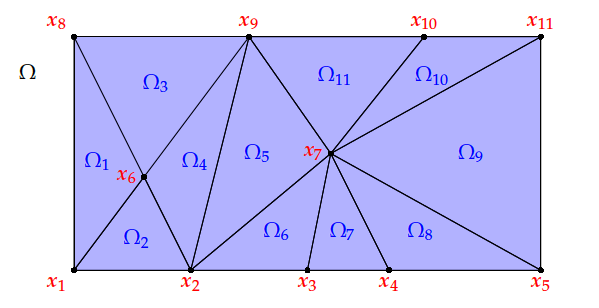

The functions $\varphi$ are uniquell defined once their values at the vertices of each triangle are known, making the vertices the degrees of freedom (DOFs). Let $\varphi_k$ be the k-th basis function of V, then 


$$\varphi_k (x_l, y_l) =0, \text{ for }l\neq k \\
\varphi_k (x_k, y_k) =1.$$


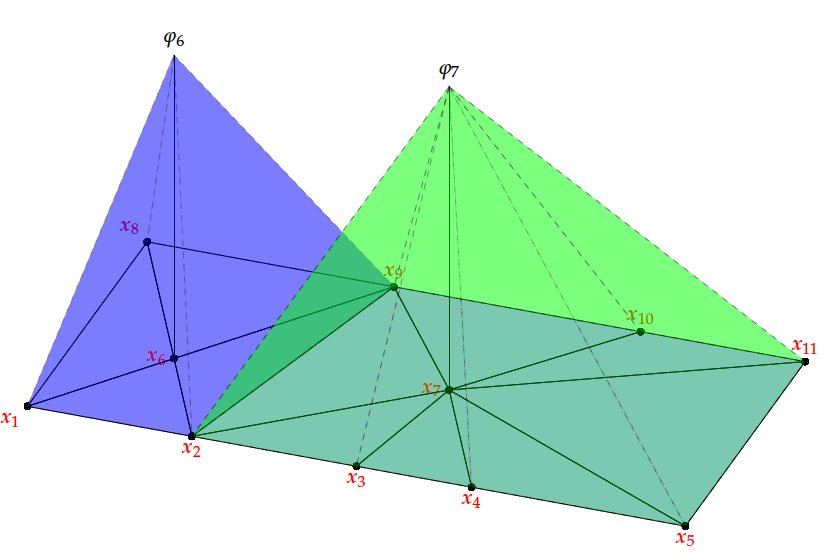

Thus, the entries of the stiffness matrix $C$can be computed on each traingle, since


$$\sum \limits_{k=1}^n \alpha_k \langle \nabla \varphi_k, \nabla \varphi_l \rangle_{\Omega} = \langle f, \varphi_l \rangle_{\Omega} + \langle h, \varphi_l \rangle_{\Gamma_2}, \text{ for }l=1,\ldots,n\\
\Leftrightarrow  \sum \limits_{k=1}^n \alpha_k \sum \limits_{\Omega_i \in \mathcal{T}} \langle \nabla \varphi_k, \nabla \varphi_l \rangle_{\Omega_i} = \langle f, \varphi_l \rangle_{\Omega} + \langle h, \varphi_l \rangle_{\Gamma_2}, \text{ for }l=1,\ldots,n \\
\Rightarrow c_{kl} = \sum \limits_{\Omega_i \in \mathcal{T}} \langle \nabla \varphi_k, \nabla \varphi_l \rangle_{\Omega_i}$$


There are only 3 basis functions not zero on a single triangle, thus one can compute the entries $c^k_{ij} =  \langle \nabla \varphi_{k_j}, \nabla \varphi_{k_i} \rangle_{\Omega_k}$. So on each single triangle a $3 \times 3$ local stiffness matrix is computed and then sorted into the global stiffness matrix. This procedure is called assembling. The management of this process if done via a DOF manager, who keeps track of the local and global coordinates.

%Construction of a mesh:
%The domain Omega = [0,1] x [0,1] shall be discretized into triangles. A possible way is teh following, with an element and ad a coordinate vector.

% The coordinate matrix of the mesh
co = [ 0  , 0  ; ...
       1/3, 0  ; ...
       2/3, 0  ; ...
       1  , 0  ; ...
       0  , 1/3; ...
       1/3, 1/3; ...
       2/3, 1/3; ...
       1  , 1/3; ... 
       0  , 2/3; ...
       1/3, 2/3; ...
       2/3, 2/3; ...
       1  , 2/3; ...
       0  , 1  ; ...
       1/3, 1  ; ...
       2/3, 1  ; ...
       1  , 1  ];

% The element matrix of the mesh
elem = [ 1 ,2 , 5; ...
         2 ,6 , 5; ...
         5 ,6 , 9; ...
         6 ,10, 9; ...
         9 ,10,13; ...
         10,14,13; ...
         2 ,3 , 6; ...
         3 ,7 , 6; ...
         6 ,7 ,10; ...
         7 ,11,10; ...
         10,11,14; ...
         11,15,14; ...
         3 ,4 , 7; ...
         4 ,8 , 7; ...
         7 ,8 ,11; ...
         8 ,12,11; ...
         11,12,15; ...
         12,16,15];
% Coordinates of the triangle number 1
co(elem(1,:),:)

ans =          0         0
    0.3333         0
         0    0.3333


# Local stiffness matrix computation

The computation of the entries of the local stiffness matrix is done by using the mapping of a triangle $\Omega_1$ onto the reference unit triangle

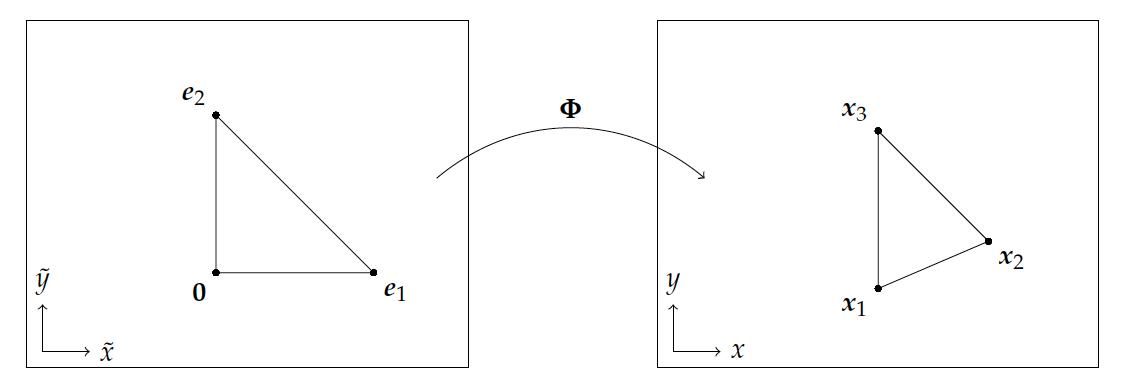

The mapping reads


$$\Phi_{k}\left(\tilde{x}\right)=\underbrace{\left (x_{k}^{2}-x_{k}^{1},  x_{k}^{3}-x_{k}^{1} \right )}\limits_{D_k :=} \tilde{x} +x_{k}^{1}$$


Using this mapping we can perform the computation of the integrals in the reference system. To this end we define


$$\tilde{\varphi}_{i}:=\varphi_{i}\circ \Phi_{k} \text{ and } \tilde{\nabla}:=\nabla_{\tilde{x}}.$$


And for the matrix entries $c_{ij}^k$ we have


$$	c_{ij}^{k}
	=
	\int\limits_{\Omega_{k}} \nabla^{\top} \varphi_{i}(x)\nabla \varphi_{j}(x)\,d x\\
	=
	\int\limits_{\Omega_{k}} \left(\nabla \tilde{\varphi}_{i}\left(\Phi_{k}^{-1}\left(x\right)\right)\right)^{\top}\left(\nabla \tilde{\varphi}_{j}\left(\Phi_{k}^{-1}\left(x\right)\right)\right)\,d x\\
	=
	\int\limits_{\Omega_{k}} \left(D_{k}^{-\top}\tilde{\nabla}^{\top} \tilde{\varphi}_{i}\left(\Phi_{k}^{-1}\left(x\right)\right)\right)\left(D_{k}^{-\top}\tilde{\nabla} \tilde{\varphi}_{j}\left(\Phi_{k}^{-1}\left(x\right)\right)\right)\,d x\\
	=
	\int\limits_{\Omega_{k}} \tilde{\nabla}^{\top} \tilde{\varphi}_{i}\left(\Phi_{k}^{-1}\left(x\right)\right)\underbrace{D_{k}^{-1}D_{k}^{-\top}}\limits_{A_{k}}\tilde{\nabla} \tilde{\varphi}_{j}\left(\Phi_{k}^{-1}\left(x\right)\right)\,d x\\
	=
	\int\limits_{\Delta} \tilde{\nabla}^{\top} \tilde{\varphi}_{i}\left(\tilde{x}\right)A_{k}\tilde{\nabla} \tilde{\varphi}_{j}\left(\tilde{x}\right)\left|\text{det}\, D_{k}\right|\,d \tilde{x}\\
	=
	\left|\text{det}\, D_{k}\right| \int\limits_{\Delta} \tilde{\nabla}^{\top} \tilde{\varphi}_{i}\left(\tilde{x}\right)A_{k}\tilde{\nabla} \tilde{\varphi}_{j}\left(\tilde{x}\right)\,d \tilde{x}.$$


% Gebiet Omega=[0,1]x[0,1], Dirichlet-Ra
nd ist der ganze Rand und rechte
% Seite ist 0.

%% mesh erzeugen, d.h. Koordinatenmatrix und Elementmatrix
co = [ 0  , 0  ; ...
       1/3, 0  ; ...
       2/3, 0  ; ...
       1  , 0  ; ...
       0  , 1/3; ...
       1/3, 1/3; ...
       2/3, 1/3; ...
       1  , 1/3; ... 
       0  , 2/3; ...
       1/3, 2/3; ...
       2/3, 2/3; ...
       1  , 2/3; ...
       0  , 1  ; ...
       1/3, 1  ; ...
       2/3, 1  ; ...
       1  , 1  ];

elem = [ 1 ,2 , 5; ...
         2 ,6 , 5; ...
         5 ,6 , 9; ...
         6 ,10, 9; ...
         9 ,10,13; ...
         10,14,13; ...
         2 ,3 , 6; ...
         3 ,7 , 6; ...
         6 ,7 ,10; ...
         7 ,11,10; ...
         10,11,14; ...
         11,15,14; ...
         3 ,4 , 7; ...
         4 ,8 , 7; ...
         7 ,8 ,11; ...
         8 ,12,11; ...
         11,12,15; ...
         12,16,15];

%% Steiffigkeitsmatrix assemblieren
n=size(co,1);
m=size(elem,1);

C=zeros(n,n);

for k=1:m
%     k1 = elem(k,1);
%     k2 = elem(k,2);
%     k3 = elem(k,3);
% 
%     nk1 = co(k1,:)';
%     nk2 = co(k2,:)';
%     nk3 = co(k3,:)';
% 
%     Dk = [ nk2-nk1, nk3-nk1 ];
% 
%     Dkinv = inv(Dk);
% 
%     gradvk1 = Dkinv'*[-1;-1];
%     gradvk2 = Dkinv'*[ 1; 0];
%     gradvk3 = Dkinv'*[ 0; 1];
% 
%     Cloc = det(Dk)/2*[ dot(gradvk1,gradvk1), dot(gradvk1,gradvk2), dot(gradvk1,gradvk3); ...
%                        dot(gradvk2,gradvk1), dot(gradvk2,gradvk2), dot(gradvk2,gradvk3); ...
%                        dot(gradvk3,gradvk1), dot(gradvk3,gradvk2), dot(gradvk3,gradvk3); ];
% 
%     C([k1,k2,k3],[k1,k2,k3])=C([k1,k2,k3],[k1,k2,k3])+Cloc;


    idx = elem(k,:);

    Dk = [ co(idx(2),:)'-co(idx(1),:)', co(idx(3),:)'-co(idx(1),:)' ];

    gradv = Dk'\[-1,1,0;-1,0,1];

    Cloc=det(Dk)/2*reshape(dot(repelem(gradv',3,1),repmat(gradv',3,1),2),3,3);

    C(idx,idx)=C(idx,idx)+Cloc;
end

%% Rechte Seite assemblieren
b=zeros(n,1);

%% Erzeugtes lineares Gleichungssystem loesen
alpha=C\b

alpha =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
